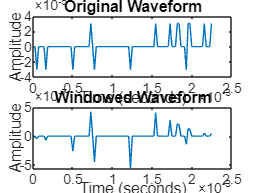

  % Define the length of the Hamming window
N = 100;

% Read the .wav file
file_path = 'gtest1.wav';
[audio_data, sample_rate] = audioread(file_path);

% Generate the Hamming window
hamming_window = 0.54 - 0.46 * cos(2 * pi * (0:N-1) / (N - 1));

% Apply the Hamming window to the audio data
windowed_audio = audio_data(1:N) .* hamming_window';

% Optionally, you can normalize the windowed audio to have unit area
windowed_audio = windowed_audio / sum(hamming_window);

% Plot the original and windowed waveforms
time = (0:N-1) / sample_rate;

figure;
subplot(2, 1, 1);
plot(time, audio_data(1:N));
title('Original Waveform');
xlabel('Time (seconds)');
ylabel('Amplitude');

subplot(2, 1, 2);
plot(time, windowed_audio);
title('Windowed Waveform');
xlabel('Time (seconds)');
ylabel('Amplitude');%}

hanning 

% Define the length of the Hanning window
N = 100;

% Read the .wav file
file_path = 'path/to/your/file.wav';
[audio_data, sample_rate] = audioread(file_path);

Error using audioread>readaudio
The filename specified was not found in the MATLAB path.

Error in audioread (line 160)
    [y, Fs] = readaudio (filename, range, datatype);


% Generate the Hanning window
hanning_window = 0.5 * (1 - cos(2 * pi * (0:N-1) / (N - 1)));

% Apply the Hanning window to the audio data
windowed_audio = audio_data(1:N) .* hanning_window';

% Optionally, you can normalize the windowed audio to have unit area
windowed_audio = windowed_audio / sum(hanning_window);

% Plot the original and windowed waveforms
time = (0:N-1) / sample_rate;

figure;
subplot(2, 1, 1);
plot(time, audio_data(1:N));
title('Original Waveform');
xlabel('Time (seconds)');
ylabel('Amplitude');

subplot(2, 1, 2);
plot(time, windowed_audio);
title('Windowed Waveform (Hanning Window)');
xlabel('Time (seconds)');
ylabel('Amplitude');


barletha

% Define the length of the Bartlett window
N = 100;

% Initialize an array for the Bartlett window
bartlett_window = zeros(1, N);

% Generate the Bartlett window
for n = 1:N
    if n <= (N+1)/2
        bartlett_window(n) = (2 / (N - 1)) * (n - 1);
    else
        bartlett_window(n) = 2 - (2 / (N - 1)) * (n - 1);
    end
end

% Plot the Bartlett window
figure;
plot(bartlett_window);
title('Bartlett Window (Manual)');
xlabel('Sample Index');
ylabel('Amplitude');

rectangual

% Define the length of the filter
N = 50;

% Initialize an array for the rectangular filter
rectangular_filter = ones(1, N);

% Plot the rectangular filter
figure;
stem(rectangular_filter);
title('Rectangular Filter (Manual)');
xlabel('Sample Index');
ylabel('Amplitude');

blachmann

% Define the length of the Blackman filter
N = 50;

% Initialize an array for the Blackman filter
blackman_filter = zeros(1, N);

% Generate the Blackman filter
for n = 1:N
    blackman_filter(n) = 0.42 - 0.5 * cos(2 * pi * (n - 1) / (N - 1)) + 0.08 * cos(4 * pi * (n - 1) / (N - 1));
end

% Plot the Blackman filter
figure;
stem(blackman_filter);
title('Blackman Filter (Manual)');
xlabel('Sample Index');
ylabel('Amplitude');
